clear;clc;close all;
set(0,'defaultlinelinewidth',3)
set(0,'defaultaxeslinewidth',2);
set(0,'defaultaxesfontsize',28);
set(0,'defaulttextfontsize',28);
set(0,'DefaultLineMarkerSize',28);
set(0,'Defaultaxesfontname','Times New Roman');
% addpath('./circleData');

% figure(); box on;
% plot(x/D,U0_axi,'-');
% xlabel('$x/D$','interpreter','latex');
% ylabel('$U_0$','interpreter','latex');
% set(gcf,'unit','centimeters','position',[20 20 20 20])

% saveas(gcf,'Re_80_U0_axi','epsc')

global tau
tau=1.5;
x=0;
p=0;

% 生成数据的个数
num = 1e6;

Hami(x,p)

ans = 0

expt(1.5)

ans = 0.3679


% 步长
a=6;

for i = 1:num
    x1 = a*(rand-0.5) + x;
    p1 = a*(rand-0.5) + p;
    if x1^2 + p1^2 < x^2 + p^2
        x = x1;
        p = p1;
    else
        xi=rand;
        if xi < expt(Hami(x1,p1)-Hami(x,p))
            x = x1;
            p = p1;
        end
    end
    X(i) = x;
    Y(i) = p;
end



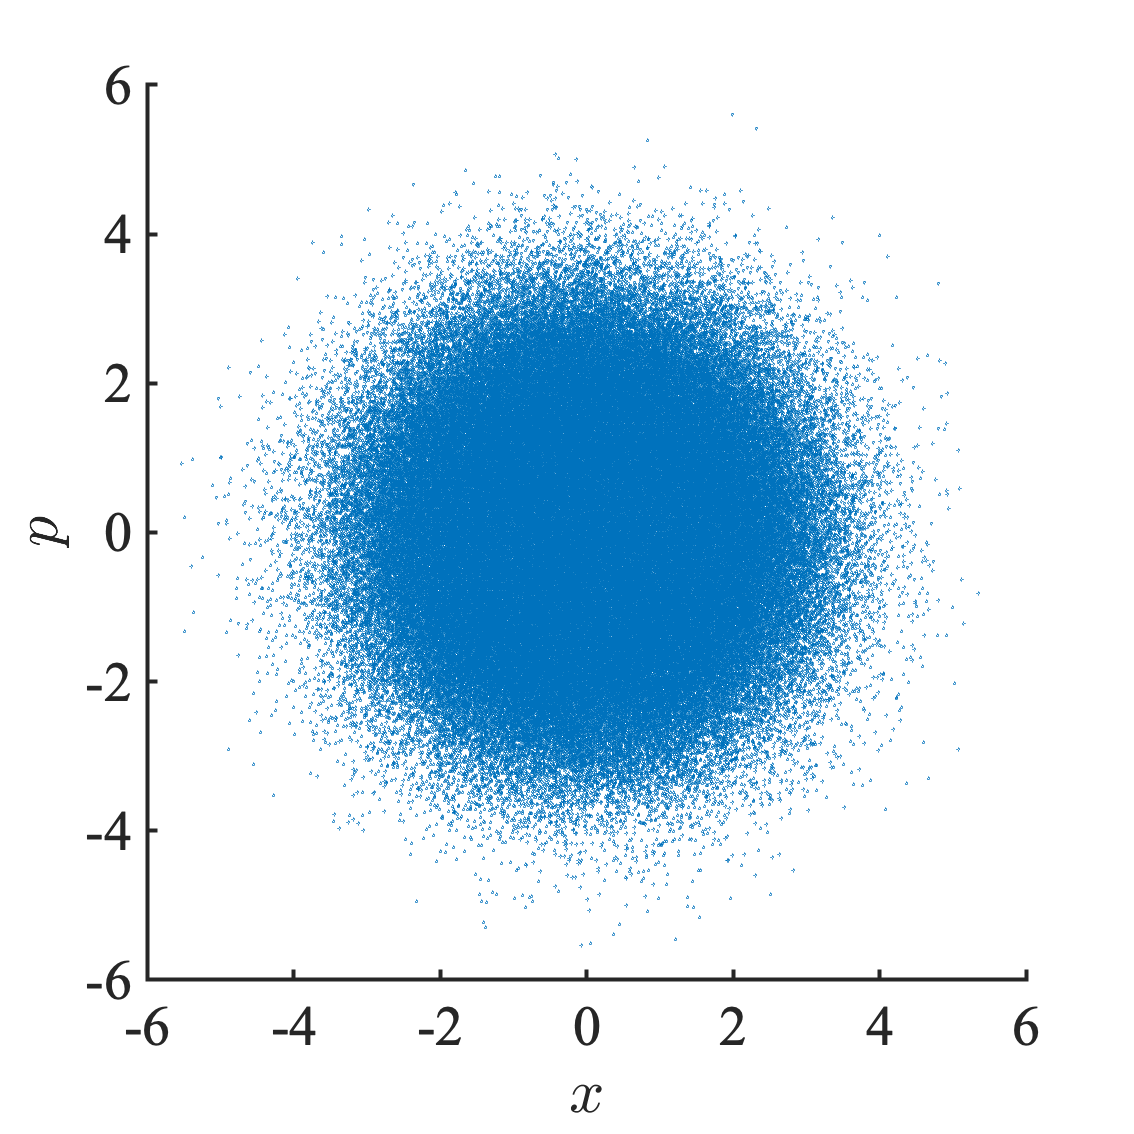


scatter(X,Y,2)

xlabel('$x$','interpreter','latex');
ylabel('$p$','interpreter','latex');
xlim([-6 6])
set(gcf,'unit','centimeters','position',[20 20 20 20])

saveas(gcf,'1','epsc')


n = 50;
X1 = linspace(-6,6,n);
Y1 = linspace(-6,6,n);
% z = 0;
for i = 1:n
    for j = 1:n
        item = 0;
        for k = 1:num
            if X(k) > X1(i) && X(k) < X1(i) + 12/n && Y(k) > Y1(j) && Y(k) < Y1(j) + 12/n
                item = item + 1;
            end
        end
        z(i,j) = item / num;
    end
end
[X1,Y1] = meshgrid(X1,Y1);

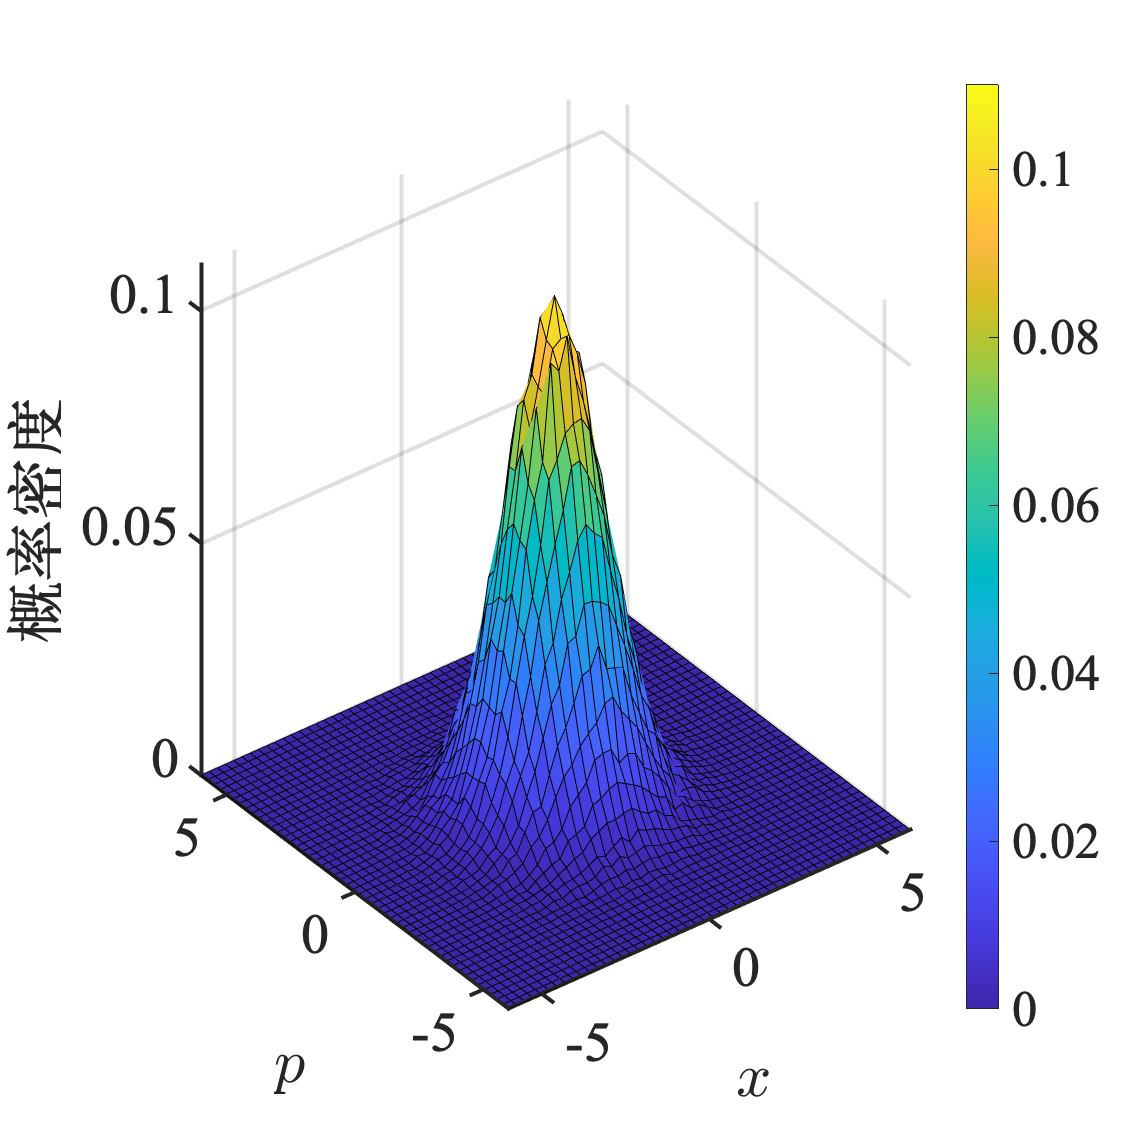



surf(X1,Y1,z/(12/n)^2)

xlabel('$x$','interpreter','latex');
ylabel('$p$','interpreter','latex');
zlabel('概率密度');
xlim([-6 6])
ylim([-6 6])
set(gcf,'unit','centimeters','position',[20 20 20 20])
colorbar
saveas(gcf,'2','epsc')

function H = Hami(x, p)
    H = 0.5*(x^2+p^2);
end

function e = expt(H)
    global tau
    e = exp(-H/tau);
end





















